clear
clc
close all
% Hello, this script calculates a steerable DMA beampattern 
% based on "Steering Study of Linear Differential Microphone Arrays". 

% Only works for distinct nulls right now (Q has other equation for null multiplicity)

% To-do:

% Order of ideal function
N = 4

N = 4


% Number of microphones M > N 
M = N +3

M = 7

%M = 15;
 
% Steering of main lobe
steerAng =151.01

steerAng = 151.0100

xs = cosd(steerAng);                 

% Minimum and maximum frequency
f_min = 0;
f_max = 24e3;

% Signal frequency to design filter (Hz)
f = f_max; % (Invariant)

% Frequency sweep list
freqs = linspace(f_min, f_max, (f_max-f_min)/(100)+1);
freqs(1) = 20;
%freqs = linspace(400, 8000, 39);
% Speed of sound (m/s)
%c = 343;  
c = 1496;

% Microphone spacing (m)
d = 0.01;
%d = (c/f_max)*0.1
%d = 0.015;

% Temporary null vector, dim = N - 1
nullAngles = [flip((steerAng-180/N:-180/N:0)) (steerAng+180/N:180/N:180)]' 

nullAngles =    16.0100
   61.0100
  106.0100


%nullAngles = [145]

%%%
% nullAngles = [100 150]'   %FSDLMA-III
% N = 3;                      %FSDLMA-III
% M = 4;
% steerAng = 45.1             %FSDLMA-III
% xs = cosd(steerAng)         %FSDLMA-III
%%%

% Concat with steering angle
x = [xs; cosd(nullAngles)]; 

% Set up linear system of equations
epsi = diag(0:N);
Q = cat(1, [(x(1).^(0:N)); (x(1).^(0:N)*epsi)], x(2:end).^(0:N));

% Inverse with constraint function
a = Q\eye(length(Q),1);

% Determine last null
xN = - a(end-1)/a(end) - sum(x(2:end))

xN = -1.2137


% Determined null vector
x = [x; xN]      

x =    -0.8747
    0.9612
    0.4847
   -0.2758
   -1.2137



% Generate input
ang_resolution = 360;
thetas = linspace(0, 2*pi,ang_resolution);
output = zeros(length(freqs),length(thetas));
wng = zeros(1,length(freqs));
df = zeros(1,length(freqs));
dfIntegral = zeros(1,length(freqs));
dfalt = zeros(1,length(freqs));

for k=1:length(freqs)
    % Every th in freqs
    D = exp((-1i*2*pi*ceil(freqs(k)/5e3)*5e3*d*(0:M-1).*x)/c); 
    
    % % Phase vector of microphone array
    %D = exp((-1i*2*pi*freqs(k)*d*(0:M-1).*x)/c);
    if M == N + 1
        h = D\eye(N+1,1);
    else
        h = D'*inv(D*D')*eye(N+1,1);
    end
    % Normalise weights
    %h = h / sum(abs(h));

    % White noise gain
    wng(k) = 10*log10(power(abs(h'*(exp((-1i*2*pi*freqs(k)*d*(0:M-1).*xs)/c))'),2)/(h'*h));

    % Directivity factor
    % gamma = diag(ones(M,1));
    % for i = 1:M
    %     for j = 1:M
    %         gamma(i,j) = (sin(2*pi*freqs(k)*(j-i)*d/c))/(2*pi*freqs(k)*(j-i)*d/c);
    %     end
    % end
    % gamma(isnan(gamma)) = 1;
    % df(k) = 10*log10(abs(power(abs(h'*(exp((-1i*2*pi*freqs(k)*d*(0:M-1).*xs)/c))'),2)/(h'*gamma*h))); % 2nd abs does nothing but remove +0i
    

    % Beam pattern
    Y = exp(-1i*2*pi*freqs(k)*d*(0:M-1).*cos(thetas(:))/c)'; 
    
    output(k,:) = h'*Y;
    dfPower = abs(power(output,2));

    % Approximate integral through trapezoidal
    dfIntegral(k) = 0.5*(thetas(2)-thetas(1))*(dfPower(k,1)*sin(thetas(1)) + ...
        2*dfPower(k,2:end/2-1)*sin(thetas(2:end/2-1))' + dfPower(k,end/2)*sin(thetas(end/2)));
    dfalt(k) = 10*log10(power(abs(h'*(exp((-1i*2*pi*freqs(k)*d*(0:M-1).*xs)/c))'),2)/(0.5*dfIntegral(k))) ;
end

bp = abs(output);
mindB = -50;
logOutput = mag2db(bp);
logOutput(logOutput < mindB) = mindB;
%save("DFandWNG" + string(M)+ ".mat", 'df', 'wng')

## Call plot-functions

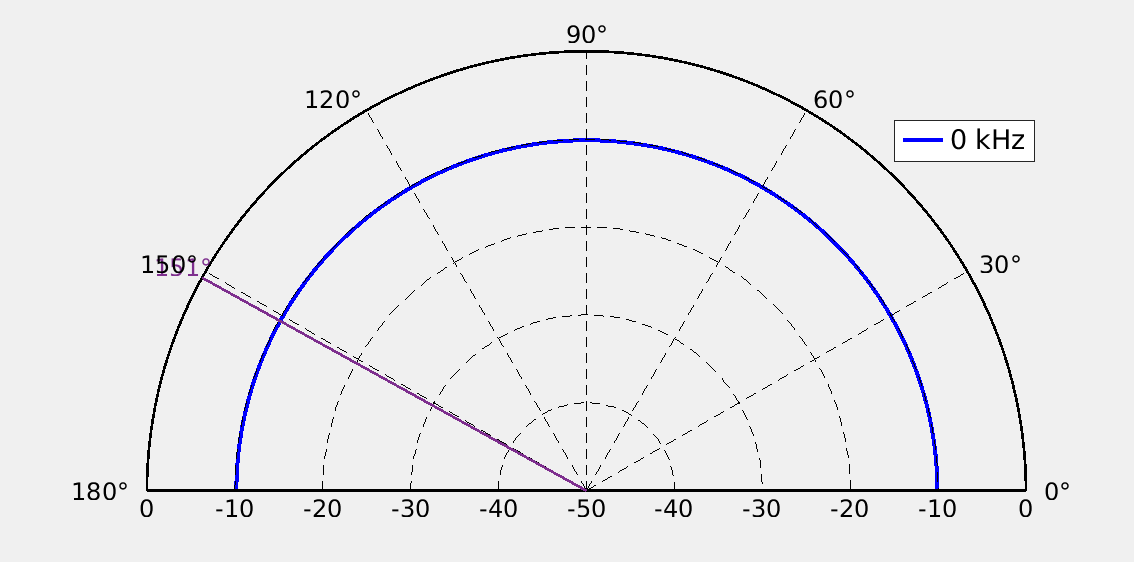

indexHz = find(freqs==20); % Find design frequency in sweep list
plotVisibility = 'on';
figure(1)
set(gcf,'Visible',plotVisibility, 'Units', 'centimeters',...
          'OuterPosition', [0 0 30 20]) %21/2-2*2
circPlot(freqs(indexHz), thetas, logOutput(indexHz,:), steerAng)

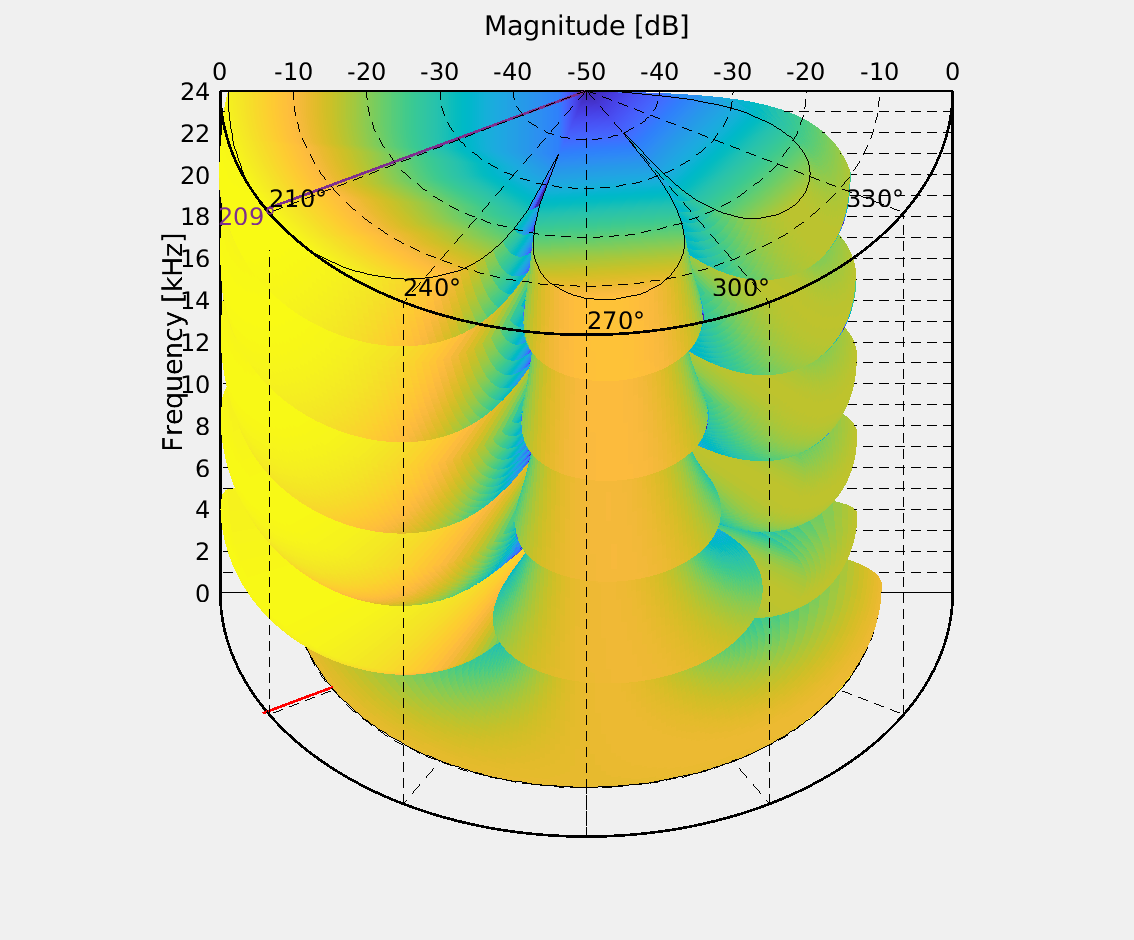

%exportgraphics(gcf,'DMAHz4N.pdf')

figure(2)
set(gcf,'Visible',plotVisibility, 'Units', 'centimeters',...
          'OuterPosition', [0 0 30 30])
cylindricalPlot(freqs, thetas, logOutput, steerAng)

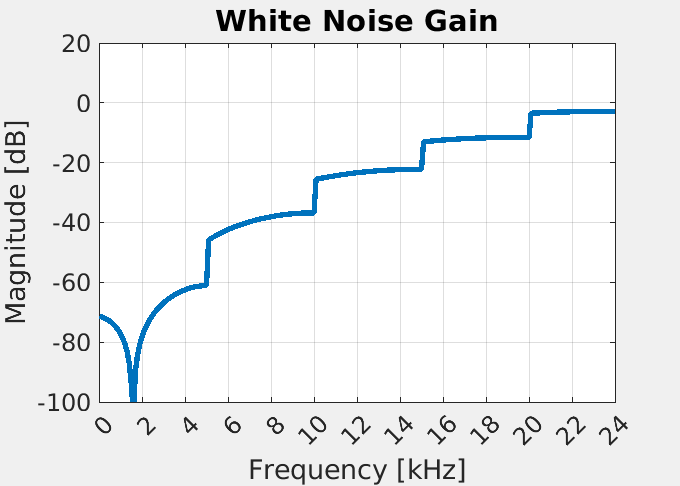

%exportgraphics(gcf,'DMA3D4N.pdf')

% Mlist = [3 5 7 9 11 13 15]
% for m = 1:length(Mlist)
%     df(m,:) = cell2mat(struct2cell(load("DFandWNG" + string(Mlist(m)) + ".mat", 'df')));
%     wng(m,:) = cell2mat(struct2cell(load("DFandWNG" + string(Mlist(m)) + ".mat", 'wng')));
% end
figure(3)
set(gcf,'Visible',plotVisibility, 'Units', 'centimeters',...
          'OuterPosition', [0 0 18 18])
plot(freqs, wng, 'LineWidth', 4)
hold on
xlim([0 f_max])
ylim([-100 20])
ytickList = linspace(-100,20,10+3);
yticks(ytickList(1:2:end))
yticklabels(string(ytickList(1:2:end)))
xtickList = linspace(f_min,f_max,f_max/1000+1);
xticks(xtickList(1:2:end))
xticklabels(string(xtickList(1:2:end)/1000))
ax = gca;
ax.FontSize = 18;
xlabel('Frequency [kHz]', 'FontSize', 20)
ylabel('Magnitude [dB]', 'FontSize', 20)
title('White Noise Gain', 'FontSize', 22)
grid
%legend('M=' + string(Mlist), 'Location', 'southeast')
hold off

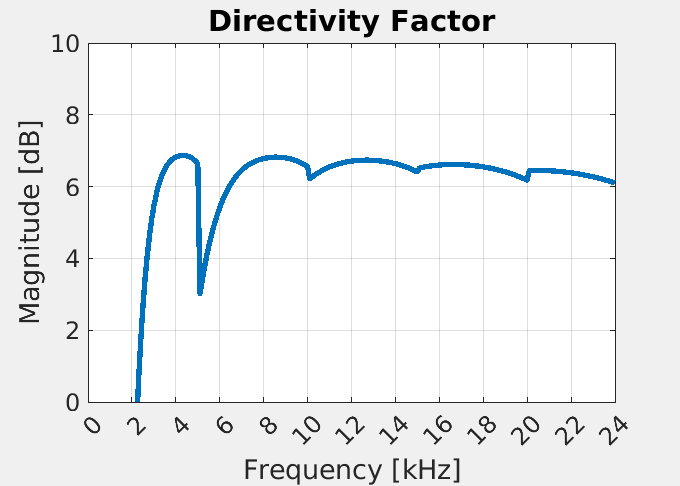

%exportgraphics(gcf,'DMAWNG4N.pdf')

figure(4)
set(gcf,'Visible',plotVisibility, 'Units', 'centimeters',...
          'OuterPosition', [0 0 18 18])
plot(freqs, dfalt, 'LineWidth', 4)
hold on
xlim([0 f_max])
ylim([0 10])
ytickList = linspace(0,10,10+1);
yticks(ytickList(1:2:end))
yticklabels(string(ytickList(1:2:end)))
xtickList = linspace(f_min,f_max,f_max/1000+1);
xticks(xtickList(1:2:end))
xticklabels(string(xtickList(1:2:end)/1000))
ax = gca;
ax.FontSize = 18;
xlabel('Frequency [kHz]', 'FontSize', 20)
ylabel('Magnitude [dB]', 'FontSize', 20)
title('Directivity Factor', 'FontSize', 22)
grid
%legend('M=' + string(Mlist), 'Location', 'northwest')
hold off

%exportgraphics(gcf,'DMADF4N.pdf')